# `HomeWork n.2 2021/22`

### `Madonna Enrico 0124002279`

1.**  Interpolazione**

**Definire un dominio **$[a,b]$** ed una funzione composta **$f(x)$** in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale **$f$**sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB *****ezplot *****per osservarne il grafico. **


$$f\left(x\right)=e^x \cdot \frac{\cos \left(x\right)}{4}+2x\cdot \log \left(x+3\right)$$


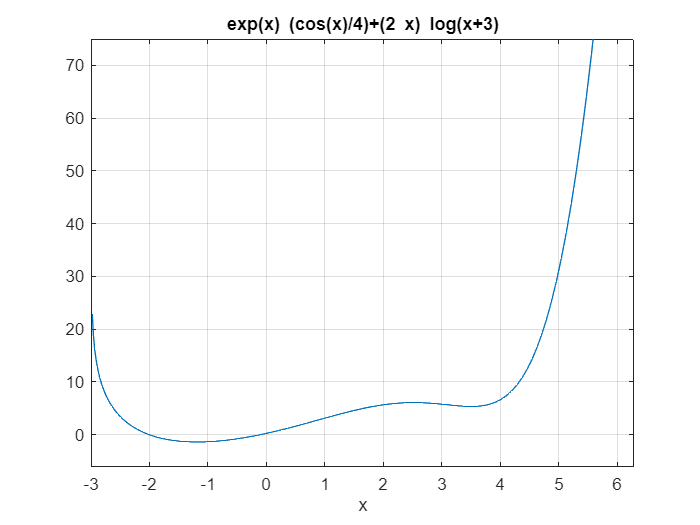

format long %Imposto tutti i numeri in formato long, come richiesto
f= @(x) exp(x).*(cos(x)./4)+(2.*x).*log(x+3);%creo la mia funzione composta

figure(1)
ezplot(f)%come suggerito, visualizzo la funzione per scegliere un intervallo utilizzanfo la funzione ezplot
grid on

*Dominio scelto: [-2, 4]*

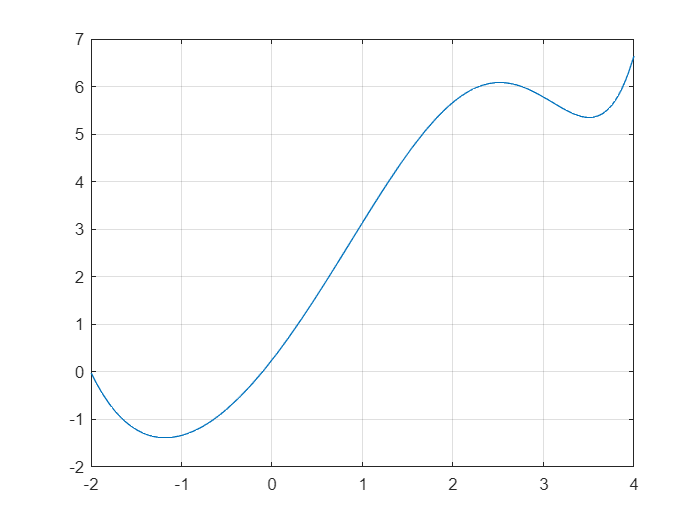

a=-2;%scelgo il mio dominio
b=4;

figure(2)
fplot(f,[a b])%visualizzo la funzione nell'intervallo [a,b]
axis([a b -2 7]);
grid on

**1.1 Definire quindi un insieme di **$m$** punti **$P=\{(x_i,y_i)\}_{i=1}^m$** con **$11 \leq m \leq 21, m \in \mathbb{N}$**. Le ascisse di **$P$** sono linearmente distribuite in **$[a,b]$**, le ordinate sono i corrispondenti valori assunti dalla valutazione di **$f(x)$**.**

Scelgo m=12 punti da distribuire linearmente lungo la funzione:

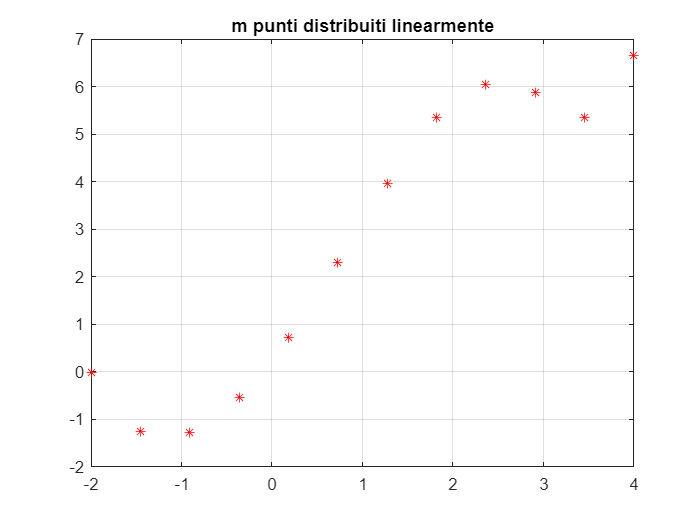

m=12;%scelgo m
x=linspace(a,b,m)';% punti di valutazione 
y=f(x);%ottengo i valori
figure(3)
plot(x,y,'*','Color','r')%plotto gli m punti distribuiti linearmente
grid on
title("m punti distribuiti linearmente")

**1.1. Definire un insieme **$\mathcal{F}$**di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio **$p$  $\in$ $\mathcal{F}$** che interpola **$f$** nei nodi **$x_i$**. Costruire e risolvere il relativo sistema lineare **$Ba=y$** (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice **$B$**.**


$$f\left(x\right)=a_1 +a_2 {x+a}_3 {x^2 +a}_4 {x^3 +a}_5 {x^4 +a}_6 {x^5 +a}_7 {x^6 +a}_8 {x^7 +a}_9 {x^8 +a}_{10} {x^9 +a}_{11} {x^{10} +a}_{12} x^{11}$$


%costruisco la matrice di Van der Monde
B = [ones(size(x)) x x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8 x.^9 x.^10 x.^11]

B = 	1.0e+06 *

   0.000001000000000  -0.000002000000000   0.000004000000000  -0.000008000000000   0.000016000000000  -0.000032000000000   0.000064000000000  -0.000128000000000   0.000256000000000  -0.000512000000000   0.001024000000000  -0.002048000000000
   0.000001000000000  -0.000001454545455   0.000002115702479  -0.000003077385424   0.000004476196981  -0.000006510831972   0.000009470301051  -0.000013774983347   0.000020036339413  -0.000029143766420   0.000042390932974  -0.000061659538871
   0.000001000000000  -0.000000909090909   0.000000826446281  -0.000000751314801   0.000000683013455  -0.000000620921323   0.000000564473930  -0.000000513158118   0.000000466507380  -0.000000424097618   0.000000385543289  -0.000000350493899
   0.000001000000000  -0.000000363636364   0.000000132231405  -0.000000048084147   0.000000017485144  -0.000000006358234   0.000000002312085  -0.000000000840758   0.000000000305730  -0.000000000111175   0.000000000040427  -0.000000000014701
   0.000001000000000

aa=Sgauss_pivot(B,y)%risolvo il sistema lineare con Gauss

aa =    0.249995856220521
   2.447244619638906
   0.666707056167147
  -0.194592727191728
  -0.016953500967114
  -0.014321762084736
   0.001519955697225
  -0.000089365647701
   0.000287045384671
  -0.000046561380710


cond(B)%calcolo indice di condizionamento della matrice B

ans =      8.535445996196815e+07


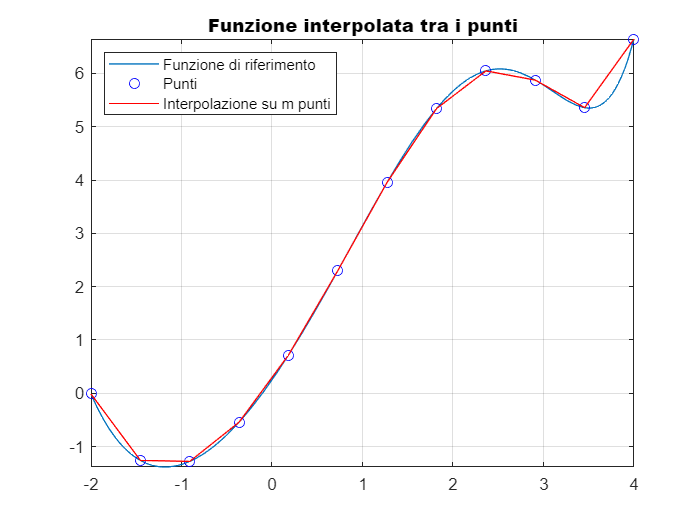

x_interpol = linspace(a,b,m);%griglia di valutazione
y_interpol = polyval(aa(end:-1:1),x_interpol);%valori sulla griglia

figure(4)
fplot(f,[a b])%visualizzo la mia funzione
hold on
grid on
plot(x,y,'ob',x_interpol,y_interpol,'r')%visualizzo gli m punti interpolati
title('Funzione interpolata tra i punti', 'FontName','Arial Black')
legend('Funzione di riferimento', 'Punti','Interpolazione su m punti', 'Location','northwest')
hold off

**1.2. Valutare il polinomio **$p$** su una griglia di **$N$** punti di valutazione distribuiti casualmente in **$[a,b]$**. Fissare **$N\,\,( 201 \leq N \leq 399)$**. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.**

Scelgo Nr=220.

Nr=220;%scelgo Nr
xx = sort((b-a)*rand(1,Nr)+a)%ottengo la griglia di valutazione composta da Nr punti distribuiti casualmente

xx =   -1.972194655195595  -1.928587582992552  -1.907579374090670  -1.809002921735476  -1.793323516982547  -1.785729928554863  -1.741857190053153  -1.722971656213076  -1.702073418045547  -1.676299288000357  -1.641322742317065  -1.544874262621618  -1.544199849854949  -1.530946827480898  -1.513245386805288  -1.497071732018405  -1.493384926934538  -1.421272848989668  -1.417209312584915  -1.414757570003543  -1.360083378916494  -1.332783468237275  -1.286013910649740  -1.260086390989007  -1.238079102238964  -1.220562749157619  -1.208160244361990  -1.183588647748018  -1.168253343027925  -1.148681968236708  -1.130271210657639  -1.126766117691698  -1.104235966645655  -1.085731886184662  -1.054321509934710  -1.026906150840543  -1.024329588832217  -1.006107623001314  -0.986059823223774  -0.975751717112848  -0.972879873130629  -0.908917830182885  -0.898933065576382  -0.896553270305500  -0.878764372673728  -0.866269909804733  -0.831414262597704  -0.820428497412751  -0.753546243601829  -0.6571283630

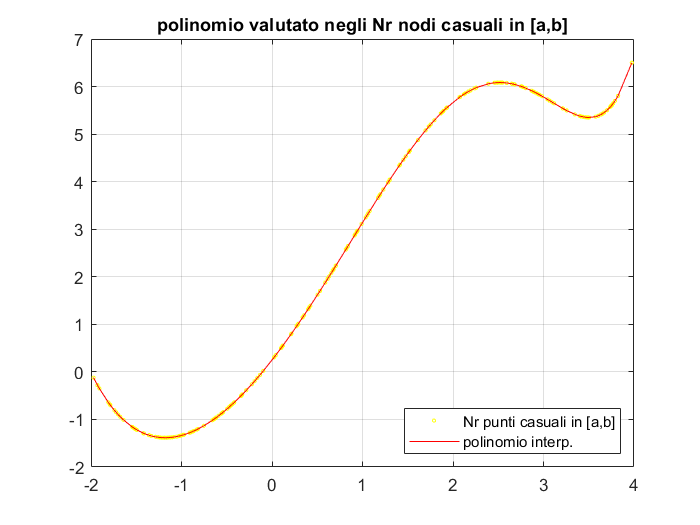

yy = polyval(aa(end:-1:1),xx);%ottengo i valori

figure(5)
plot(xx,yy,'yo','MarkerSize',2)%visualizzo gli Nr punti casuali
hold on
grid on
plot(xx,yy,'-r')%visualizzo la Valutazione polinomio
axis([a b -2 7])
legend("Nr punti casuali in [a,b]","polinomio interp.","Location","southeast")
title('polinomio valutato negli Nr nodi casuali in [a,b]')
hold off

Calcolo anche l'errore di interpolazione

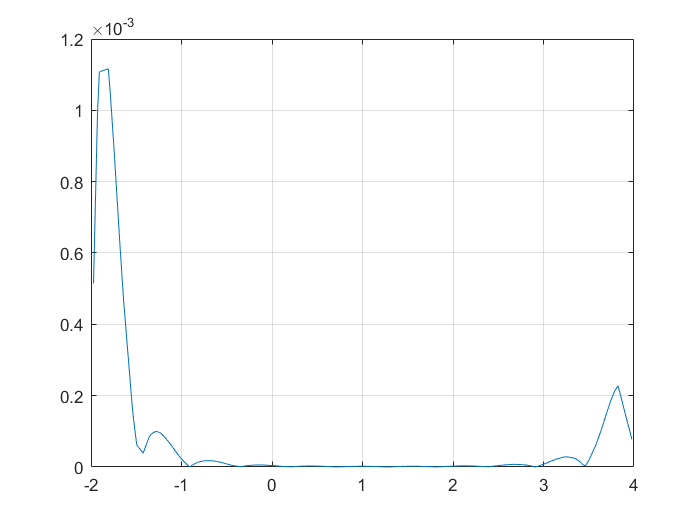

err_int = abs(yy - f(xx));%calcolo l'errore di interpolazione
figure(6)
plot(xx, err_int)%visualizzo l'andamento dell'errore
grid on
hold off

     **  1.3. Interpolare i punti **$P$** mediante una spline **$s$** di terzo grado di tipo *****not-a-knot*****.  Valutare l'interpolante ottenuto sulla una griglia di **$N$** punti di valutazione.**

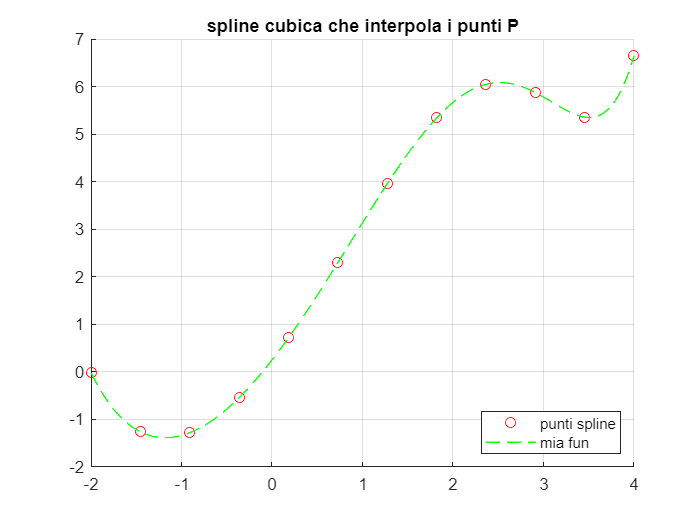

xspline = linspace(a,b,m);%griglia spline su m punti
yspline = spline(x,y,xspline);%valori spline

figure(7)
hold on
grid on
plot(xspline,yspline,'ro')
fplot(f, [a b],'--g')
axis([a b -2 7])
title("spline cubica che interpola i punti P")
legend("punti spline","mia fun" ,'Location','southeast')
hold off

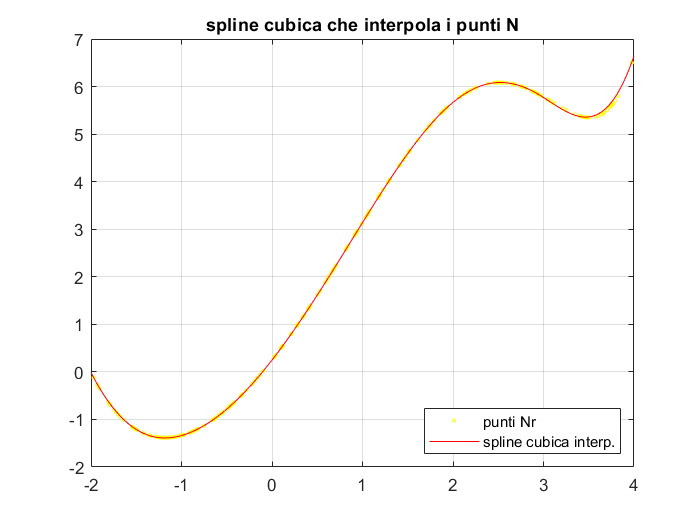


xxspline = linspace(a,b,Nr);%griglia spline su Nr punti
yyspline = spline(x,y,xxspline);%nuovi valori spline 

figure(8)
plot(xx,yy,'yo','MarkerSize',2)%visualizzo gli Nr punti
hold on
plot(xxspline,yyspline,'r')%visualizzo l'interpolazione
axis([a b -2 7])
grid on
title("spline cubica che interpola i punti N")
legend("punti Nr","spline cubica interp." ,'Location','southeast')
hold off

**        1.4. Fissare un valore **$n\,\,( 10 \leq n \leq 19)$** e definire un nuovo insieme di punti **$Q = \{(x_j, y_j)\}_{j=1}^n$** le cui ascisse sono i nodi di Chebyshev in **$[a,b]$** e le cui ordinate sono i valori corrispondenti assunti da **$f(x)$**. Costruire il polinomio interpolante i punti **$Q$** e valutarlo sulla griglia di valutazione generata al punto 1.2.**

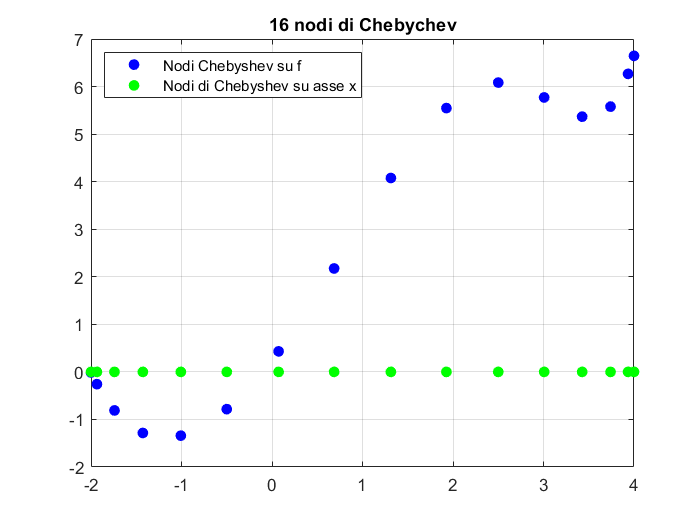

n_cheb = 16;%scelgo il numero di punti Q


x_cheb = 0.5*(a+b)+0.5*(b-a)*cos([0:n_cheb-1]*pi/(n_cheb-1));% calcola n nodi di Chebychev per l'intervallo [a,b], Avrei potuto anche usare la funzione AscisseCheb
x_cheb = x_cheb(end:-1:1);

y_cheb=f(x_cheb);%ottengo i valori

figure(9)
plot(x_cheb,y_cheb,'.b','MarkerSize',22)%visualizzo i nodi di cheb
grid on
hold on
plot(x_cheb,0,'.g','MarkerSize',22)%e li proietto sull'asse x
title('16 nodi di Chebychev')
legend('Nodi Chebyshev su f','Nodi di Chebyshev su asse x','Location','northwest')
hold off

**Costruire il polinomio interpolante i punti **$Q$** e valutarlo sulla griglia di valutazione generata al punto 1.2.**

x_cheb=x_cheb';
y_cheb=y_cheb';
%costruisco un altro polinomio interpolante 
B_cheb = [ones(size(x_cheb)) x_cheb x_cheb.^2 x_cheb.^3 x_cheb.^4 x_cheb.^5 x_cheb.^6 x_cheb.^7 x_cheb.^8 x_cheb.^9 x_cheb.^10 x_cheb.^11 x_cheb.^12 x_cheb.^13 x_cheb.^14 x_cheb.^15]

B_cheb = 	1.0e+09 *

   0.000000001000000  -0.000000002000000   0.000000004000000  -0.000000008000000   0.000000016000000  -0.000000032000000   0.000000064000000  -0.000000128000000   0.000000256000000  -0.000000512000000   0.000001024000000  -0.000002048000000   0.000004096000000  -0.000008192000000   0.000016384000000  -0.000032768000000
   0.000000001000000  -0.000000001934443   0.000000003742069  -0.000000007238818   0.000000014003080  -0.000000027088157   0.000000052400491  -0.000000101365753   0.000000196086251  -0.000000379317637   0.000000733768273  -0.000001419432755   0.000002745811476  -0.000005311615246   0.000010275015881  -0.000019876430513
   0.000000001000000  -0.000000001740636   0.000000003029815  -0.000000005273806   0.000000009179779  -0.000000015978657   0.000000027813031  -0.000000048412374   0.000000084268339  -0.000000146680537   0.000000255317477  -0.000000444414887   0.000000773564718  -0.000001346494884   0.000002343757972  -0.000004079630375
   0.00000000100

aa_cheb = Sgauss_pivot(B_cheb,y_cheb)%risolvo il sistema lineare

aa_cheb =    0.249998130834998
   2.447249381310407
   0.666686825287607
  -0.194566601605351
  -0.016991810654464
  -0.014332522407739
   0.001616594595499
  -0.000161005363352
   0.000269205720498
  -0.000004480203802


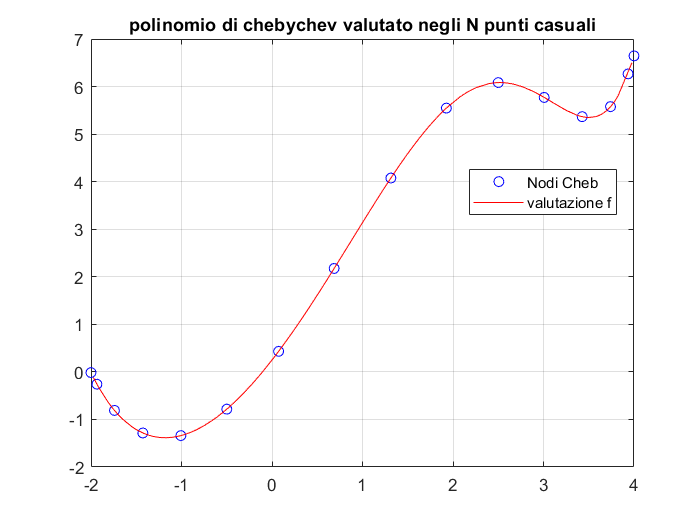

yy_cheb = polyval(aa_cheb(end:-1:1),xx);%ottengo i valori

figure (10)
plot(x_cheb,y_cheb ,'bo',xx,yy_cheb,'r')%visualizzo i nodi e l'interpolazione
axis([a b -2 7])
grid on
title("polinomio di chebychev valutato negli N punti casuali")
legend("Nodi Cheb","valutazione f","Location","best")

   **     1.5. Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2.**

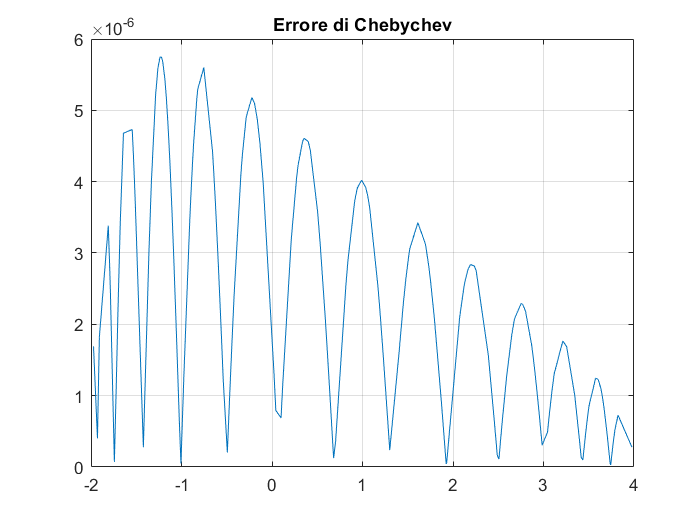

err_cheb = abs(yy_cheb - f(xx));%trovo l'errore di interpolazione
figure(11)
plot(xx, err_cheb)
grid on
title("Errore di Chebychev")
hold off

Effettuo il confronto con i valori ottenuti dal punto 1.2:

confronto_err = abs(err_cheb - err_int)%effettuo il confronto punto per punto

confronto_err =    0.000513167229580   0.000988159189204   0.001105952608077   0.001113118405491   0.001066541029459   0.001041556673845   0.000877036080423   0.000798415183402   0.000710542050136   0.000604004646298   0.000467354514639   0.000166679631800   0.000165024727688   0.000133779888416   0.000095788104547   0.000064721098012   0.000058114171214   0.000038593540199   0.000042364667014   0.000044562219244   0.000079764960909   0.000088827193144   0.000094277552252   0.000093019176666   0.000090133320269   0.000086878298428   0.000084151632931   0.000077930801113   0.000073623019962   0.000067795028122   0.000062092023135   0.000060991157394   0.000053866145685   0.000048027654581   0.000038363953966   0.000030374622158   0.000029650977249   0.000024585260930   0.000017917369241   0.000014648806723   0.000013758821444   0.000003414804570   0.000001763339418   0.000001384450710   0.000001270154438   0.000002950301351   0.000006865896241   0.000007875510819   0.000011963463015   0

**        1.6. Considerare il poligono di **$N$**vertici costituito dai valori della curva parametrica interpolata al punto (1.2) e, tramite il comando **`fill, `**visualizzare in una figura tale poligono colorato con un colore generato da una terna RGB.**

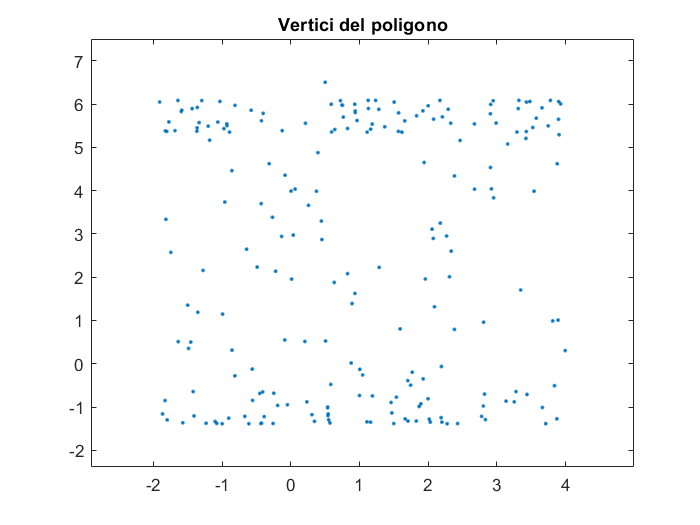

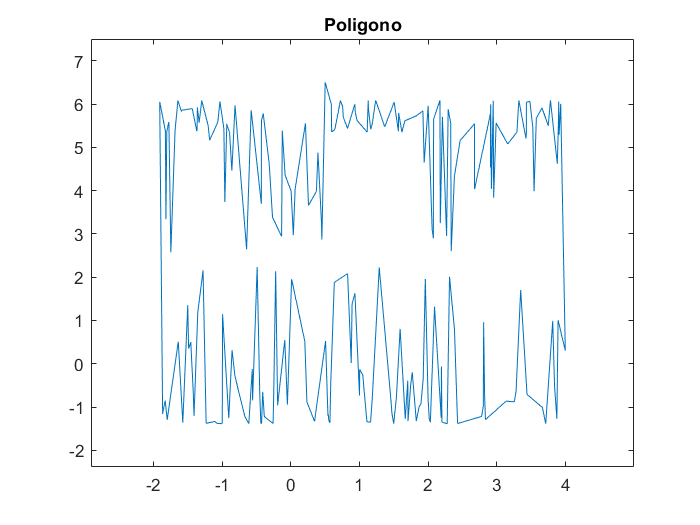

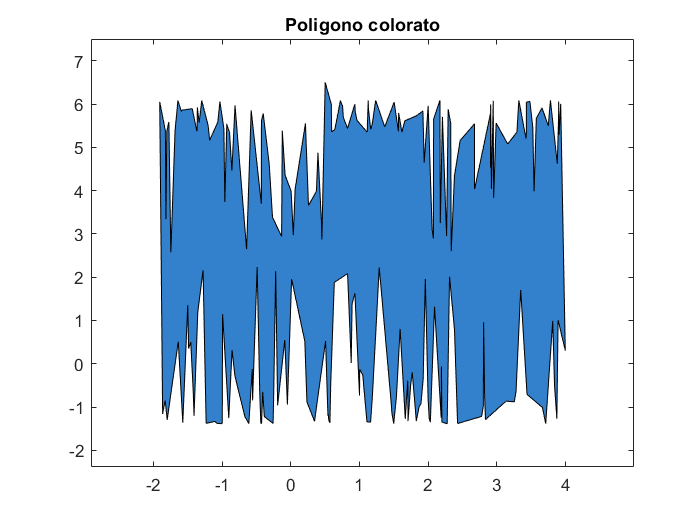

poligono(Nr,yy,b,a)%richiamo una funzione che risolve la sfida posta

** 2. Interpolazione di curve parametriche**

**  Si considerino le seguenti curve parametriche:**

**         1. **$x = 4\sin\Big(\frac{1}{4}t\Big)\quad\quad y = 1 - 2\cos^2\Big(\frac{1}{4}t\Big)\quad\quad -52\pi \leq t \leq 34\pi$

**         2. **$x = 2e^t\quad\quad y = \cos(1+e^{3t})\quad\quad  0 \leq t \leq \frac{3}{4}$

**         3. **$x = t\cos(t)\quad\quad y = t\sin(t)\quad\quad -2\pi \leq t \leq 2\pi$

**         4. **$x = \cos t
 + \frac{1}{4}\cos(8t)\quad\quad y = \sin t + \frac{1}{4}\sin(8t)\quad\quad 0\leq t \leq 2\pi$

**Scegliere una di tali curve e campionarla in **$n$** punti **$P=\{(x_i,y_i)\}_{i=1}^n$**, corrispondenti a **$n$** punti **$t_i$** equispaziati nell'intervallo **$[a,b]$** in cui varia il parametro **$t$** (fissare **$20<n<30$**). **

Scelgo la curva num. 2 : 


$$x = 2e^t\quad\quad y = \cos(1+e^{3t})\quad\quad  0 \leq t \leq \frac{3}{4}$$


e fisso n= 26.

n = 26;%fisso n=26
t = linspace(0,3/4,n);%ottengo n punti equispaziati nell'intervallo richiesto

** 2.1. /2.2 costruire due spline parametriche **$p_x$** e **$p_y$** che interpolino rispettivamente i punti **$(t_i,x_i)$** e i punti **$(t_i, y_i)$**  (**$i = 1,\ldots, n$**);  valutare le spline parametriche su una griglia fitta opportuna e mostrare il grafico della curva parametrica interpolata.**

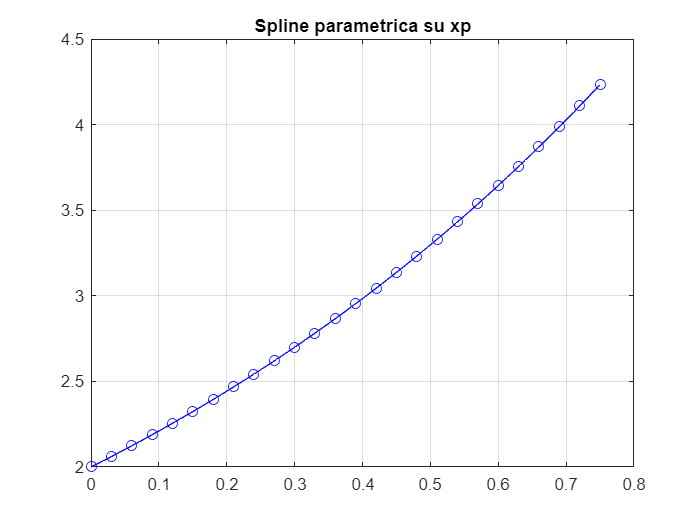

for i=1:n%campiono la curva scelta
    xp(i) = 2.*exp(t(i));% considero la funzione x della curva scelta
    yp(i) = cos(1+exp(3.*t(i)));%considero la funzione y della curva scelta
end                    
tt = linspace(0,3/4,200);% creo la griglia dei punti distribuendo i punti nell'intervallo del parametro
xsplineC = spline(t,xp,tt); %creo la spline con la funzione x della curva 
ysplineC = spline(t,yp,tt);  %creo la spline con la funzione y della curva  

figure (12)
plot(t,xp,'bo',tt,xsplineC,'b')%visualizzo la funzione spline x nell intervallo 
title('Spline parametrica su xp')
grid on

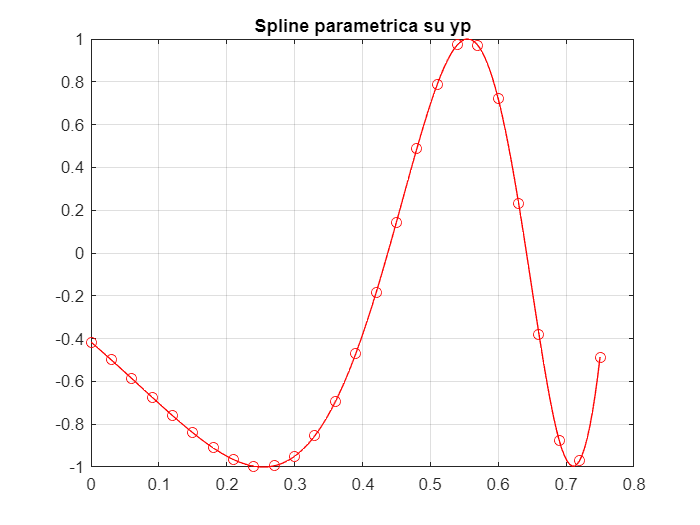

figure(13)
plot(t,yp,'ro',tt,ysplineC,'r')%visualizzo la funzione spline y nell' intervallo 
title('Spline parametrica su yp')
grid on

**    2.3.  Ripetere i punti (2.1) e (2.2) su un insieme di **$m=40$** punti **$S = \{(x_j,y_j)\}_{j=1}^m$** le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando **`ginput`** usato su una immagine a propria scelta oppurtunamente caricata (usare **`imread). `**Le coordinate devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che **`x`** e **`y`** siano i vettori delle coordinate dei vertici di un poligono (chiuso). **

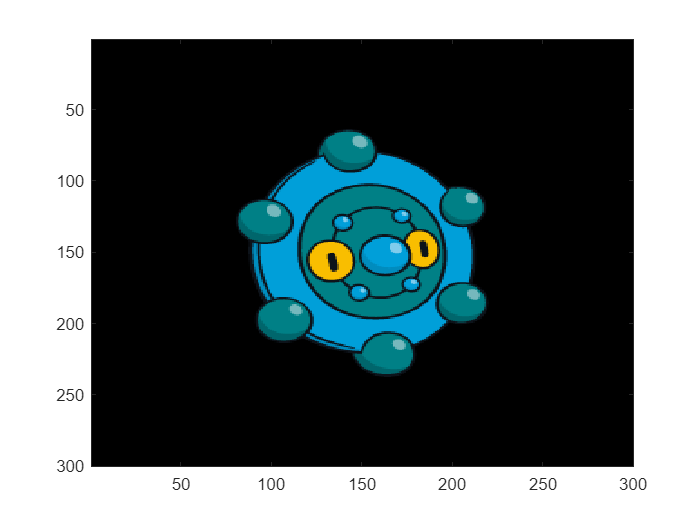

load DatiHW2.mat
%se il load falisce, caricare il percorso che porta al file DatiHW2.mat, contenente imgg,xi, yi e i dati di andamento sul covid che serviranno piu avanti

image(imgg)

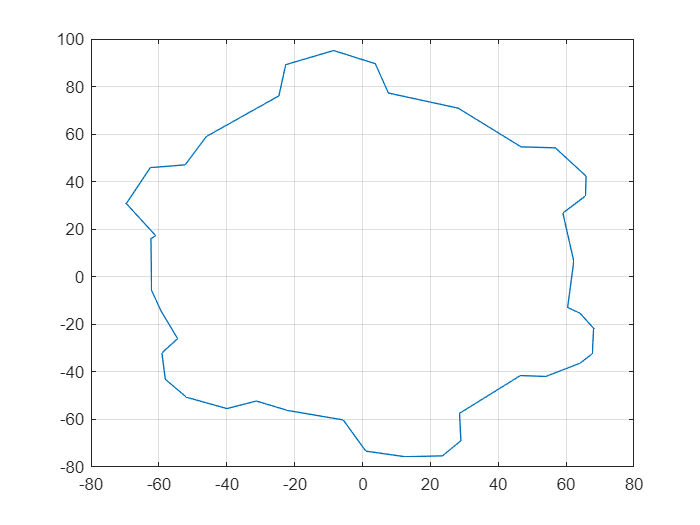

% centralizzo l'immagine
xc=mean(xi);
yc=mean(yi);
xi = xi-xc;
yi = (yi-yc);
%genero i punti fittizi che chiudono la figura
xi= [xi;xi(1)];
yi= [yi;yi(1)];
figure(16)
plot(xi,yi,0,0)
grid on

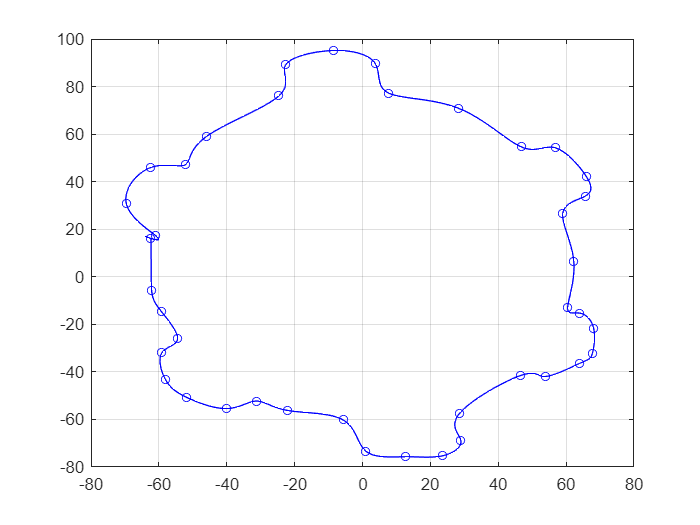


figure(17)
g = 1:length(xi);
gg = linspace(g(1),g(end),500);%creo la distribuzione dei punti scelti 

%creo la spline x e y dei punti
xispline = spline(g,xi',gg);  
yispline = spline(g,yi',gg); 

%costruisco la matrice delle coordinate generate dai punti 
miafotoS=[xispline;yispline];
plot(xi,yi,'bo',miafotoS(1,:),miafotoS(2,:),'b','markersize',5)%visualizzo 
grid on

**       2.4. Calcolare il perimetro del poligono ottenuto al punto precedente tramite un'opportuna function che sarà allegata in fondo al file **`.mlx`

perimetro(xi,yi)%calcolo il perimetro del poligono

perimetro_poligono =      5.195774720200191e+02


** 2.5. Ricostruire inoltre la curva parametrica passante per i punti definiti al punto (2.3) mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite.  **

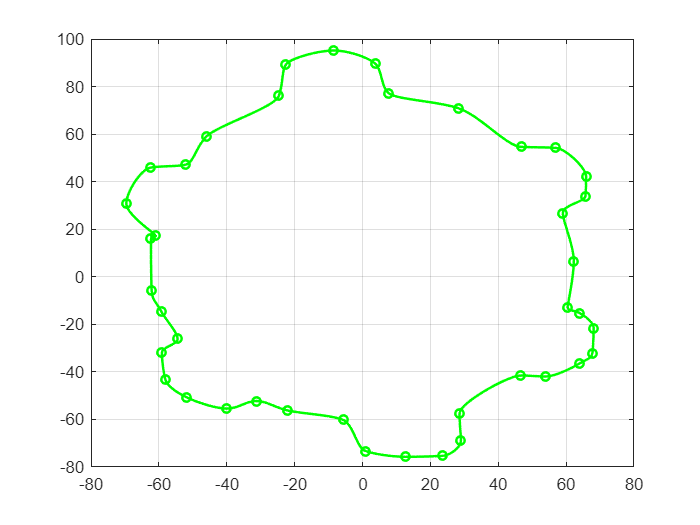

figure(18)
xcubHermN = pchip(g,xi,gg);    %spline cubica di Hermite sulla funzione x          
ycubHermN = pchip(g,yi,gg);    %spline cubica di Hermite sulla funzione y    
plot(xi,yi,'go',xcubHermN,ycubHermN,'g','markersize',5,'linewidth',1.5)%visualizzo 
grid on

norm(ycubHermN,Inf)%calcolo la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite.

ans =   95.147824901408754


**3. Approssimazione**

**Scaricare il dataset dell'andamento del covid da **[**https://github.com/pcm-dpc/COVID-19**](https://github.com/pcm-dpc/COVID-19)

**Caricare il dataset in matlab utilizzando il comando **`readtable`**.**

Data %contenuto in DatiHW2.mat

Data = 838×24 table
           data             stato     ricoverati_con_sintomi    terapia_intensiva    totale_ospedalizzati    isolamento_domiciliare    totale_positivi    variazione_totale_positivi    nuovi_positivi    dimessi_guariti    deceduti    casi_da_sospetto_diagnostico    casi_da_screening    totale_casi    tamponi    casi_testati         note         ingressi_terapia_intensiva    note_test    note_casi    totale_positivi_test_molecolare    totale_positivi_test_antigenico_rapido    tamponi_test_molecolare    tamponi_test_antigenico_rapido
    ___________________

**Generare un insieme di punti **$C=\{(t_i,y_i)\}_{i=1}^n$** le cui ascisse il tempo **$t_1,t_2,\ldots,t_n$**. I valori sono estratti dalla tabella precedentemente caricata. Scegliere una colonna a piacere che descrive un attributo della tabella. Scegliere inoltre **$5 \leq n \leq 11$**.**

num_isolamento_domiciliare = 8; %scelgo un numero tra 5 e 11

isolamento_domiciliare = Data.isolamento_domiciliare %passo la colonna dell'isolamento domiciliare alla variabile creata

isolamento_domiciliare =           94
         162
         221
         284
         412
         543
         798
         927
        1000
        1065


**         3.1 Costruire e valutare, su una griglia fitta di almeno 100 punti, utilizzando i metodi studiati, la retta dei minimi quadrati approssimante i dati.**

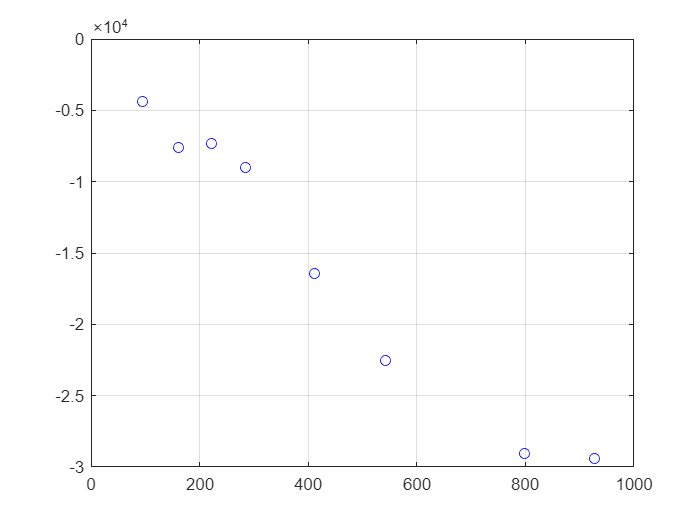

figure(19)
is_dom = 1:length(num_isolamento_domiciliare); %fisso la lunghezza della colonna 
for i=1:num_isolamento_domiciliare
    is_dom(i)=isolamento_domiciliare(i);%ciclo su ogni valore della terapia intensiva
end

is_dom = is_dom';
griglia = linspace(is_dom(1),is_dom(end),100);%creo una griglia 
coeff = -10+num_isolamento_domiciliare*rand(2,1); %creo il coefficiente per generare i punti randomici   
dati_approssimati = polyval(coeff,is_dom);
dati_approssimati = 3*dati_approssimati +5*rand(num_isolamento_domiciliare,1).*dati_approssimati*0.5;
plot(is_dom,dati_approssimati,'bo')
grid on

** 3.2. Mostrare graficamente sia il polinomio di primo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti.**

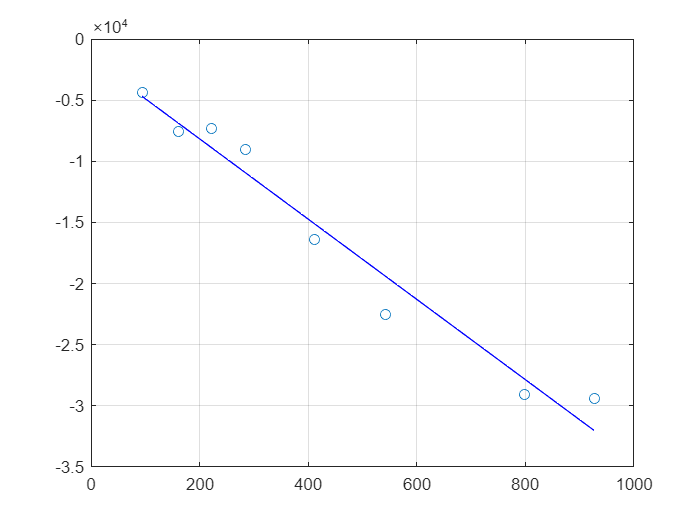

figure(20)
a2=polyfit(is_dom,dati_approssimati,1);
retta=polyval(a2,griglia);
plot(is_dom,dati_approssimati,'o',griglia,retta,'b')
grid on

**         3.3. Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 2 e 10. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.**

%creo una griglia di 100 punti e costruisco il polinomio di secondo grado da approssimare valuto l'approssimazione
xx2 = linspace(min(is_dom), max(is_dom), 100);

a3 = polyfit(is_dom,dati_approssimati, 2);
parabola2 = polyval(a3, xx2);

a4 = polyfit(is_dom,dati_approssimati, 3);
parabola3 = polyval(a4, xx2);

a5 = polyfit(is_dom,dati_approssimati, 4);
parabola4 = polyval(a5, xx2);

a6 = polyfit(is_dom,dati_approssimati, 5);

parabola5 = polyval(a6, xx2);

a7 = polyfit(is_dom,dati_approssimati, 6);

parabola6 = polyval(a7, xx2);

a8 = polyfit(is_dom,dati_approssimati, 7);

parabola7 = polyval(a8, xx2);
a9 = polyfit(is_dom,dati_approssimati, 8);

parabola8 = polyval(a9, xx2);
a10 = polyfit(is_dom,dati_approssimati, 9);

parabola9 = polyval(a10, xx2);
a11 = polyfit(is_dom,dati_approssimati, 10);

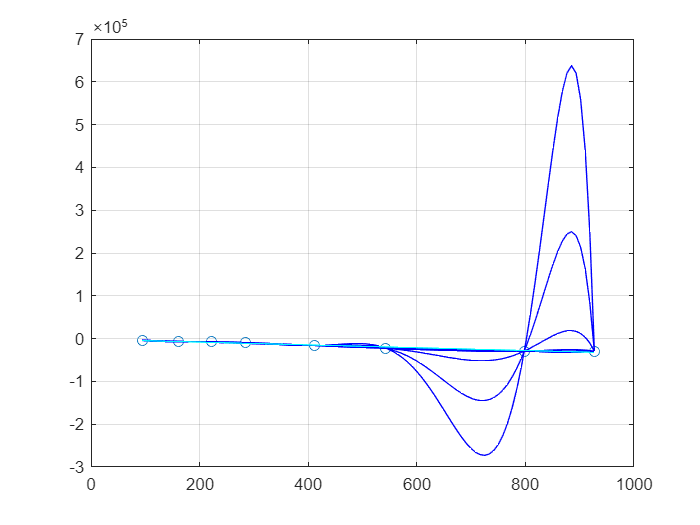

parabola10 = polyval(a11, xx2);

figure(21)
plot(is_dom,dati_approssimati,'o',xx2,parabola2,'b')%visualizzo le parabole 
hold on
grid on
plot(xx2,parabola3,'b')
plot(xx2,parabola4,'b')
plot(xx2,parabola5,'b')
plot(xx2,parabola6,'b')
plot(xx2,parabola7,'b')
plot(xx2,parabola8,'b')
plot(xx2,parabola9,'b')
plot(xx2,parabola10,'b')
plot(griglia,retta,'c')
hold off

**         3.4. Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute.**

parabola_ris = zeros(length(is_dom), num_isolamento_domiciliare); %calcolo il residuo della parabola
for i=1:8
    parabola_ris(:, i) = abs(polyval(polyfit(is_dom, dati_approssimati, i+1),is_dom)-dati_approssimati)'; %ciclo ogni parabola per calcolare i residui
end

for i=1:8
    norma2_res(i) = norm(parabola_ris(i, :), 2); %calcolo la norma 2
end

norma2_res%li visualizzo

norma2_res = 	1.0e+03 *

   1.457900705234725   2.729349406019386   1.790392456549688   3.055286861523091   1.050738768112836   1.791273676437518   1.374995315149129   1.203024839082313


**4. Quadratura**

**    4.1. Definire un dominio **$[a,b]$** ed una funzione composta **$f(x)$** in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc etc). La funzione deve essere definita, positiva e continua in **$[a,b]$**. Usare la funzione **`ezplot`** per stabilire l'intervallo **$[a,b]$**; **

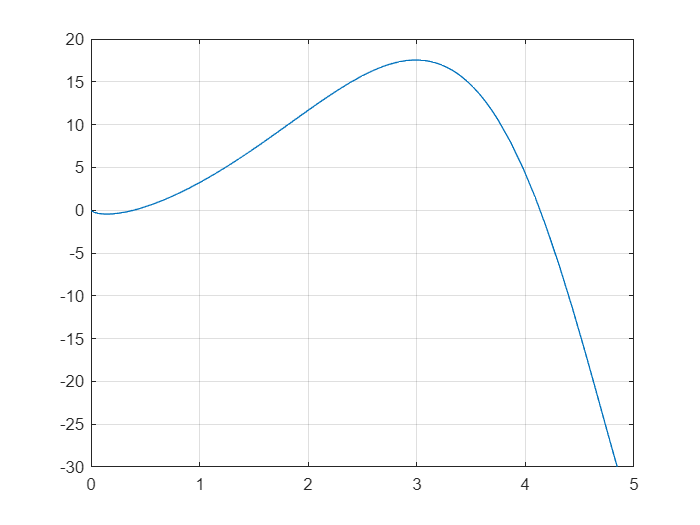

%creo funzione definita, positiva e continua in [a,b]
f1 = @(x) exp(x).*(sin(x)./2)+(3.*x).*log(x.*2);%creo la mia funzione composta

figure(22)
fplot(f1)
axis([0 5 -30 20])
grid on

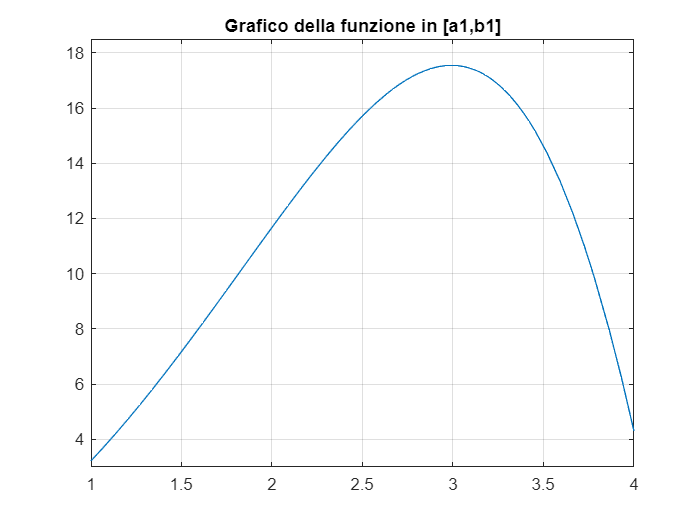

figure(23)
a1=1;%stabilisco il nuovo dominio
b1=4;
fplot(f1, [a1, b1]) %stabilisco l'intevallo
axis([1 4 3 18.5])
hold on 
grid on 
title("Grafico della funzione in [a1,b1]") 
hold off

**    4.2. Considerare come valore esatto dell'integrale **$I=I[f]=\int_a^b f(x)dx$** il valore ottenuto mediante la funzione MATLAB **`integral`** con tolleranza **$10^{-9}$**;**

integrale = integral(f1,a1,b1,'AbsTol',1e-9)%questa è la funzione integranda che ho ottenuto usando la funzione integral

integrale =   36.004139966620137


**    4.3. Stimare l'integrale **$I$** utilizzando le principali formule di quadratura (Rect. sx, Rect. dx, Punto medio, Trapez., Simpson) su **$1, 2,$** e **$3$** nodi e calcolare per ognuna di esse il corrispondente errore di discretizzazione. **

mr = (a1+b1)/2; %punto medio dell'intervallo

%utilizzo le formule che conosciamo per calcolare il punto medio, il trapezoidale e simpson
    apprRSX = (b1-a1)*f1(a1); 
    apprRDX = (b1-a1)*f1(b1);
    apprPMf = (b1-a1)*f1(mr); 
    apprTf = (b1-a1)/2*(f1(a1)+f1(b1));
    apprSf = (b1-a1)/6*(f1(a1)+4*f1(mr)+f1(b1));

format long 

RSX = apprRSX'; 
RDX = apprRDX';
PMf = apprPMf'; 
TRf = apprTf'; 
SPf = apprSf'; 

Tabella1 = table(RSX,RDX,PMf,TRf,SPf)  %genero la tabella e visualizzo i risultati

Tabella1 = 1×5 table
          RSX                 RDX                 PMf                 TRf                 SPf       
    ________________    ________________    ________________    ________________    ________________

    9.66935755580777    12.8798712240538    47.1486779515608    11.2746143899308    35.1906567643508


%calcolo gli errori di discretizzazione
Err_RSX = abs(RSX-integrale);
Err_RDX = abs(RDX-integrale);
Err_PM = abs(PMf-integrale);
Err_TR = abs(TRf-integrale);
Err_SP = abs(SPf-integrale); 
Tabella_Errori = table(Err_RSX,Err_RDX,Err_PM,Err_TR,Err_SP)%visualizzo i risultati

Tabella_Errori = 1×5 table
        Err_RSX             Err_RDX              Err_PM              Err_TR              Err_SP      
    ________________    ________________    ________________    ________________    _________________

    26.3347824108124    23.1242687425664    11.1445379849407    24.7295255766894    0.813483202269332


**    4.4. Costruzione di formule di quadratura. Fissare **$p$ $3 \leq p \leq 5$** nodi distinti, non equispaziati, **$x_i \in [0,4]$**  di una formula di quadratura **

                                                                                   
$$Q[f]=w_1f(x_1)+w_2f(x_2)+\cdots+w_pf(x_p)$$
                            

**    per il calcolo numerico dell'integrale definito della funzione **$f$** in **$[0,4]$**;**

p = 3; %nodi distinti

ai = 0; bi = 4; %intervallo

mq = (ai+bi)/2;%reimposto il nuovo punto medio dell'intervallo

GQ = (bi-ai)*rand(p,1)+ai;%genero i nodi randomici ed equispaziati passando per nodi distinti

GQ = sort(GQ)

GQ =    0.328284828390903
   0.422837706326886
   3.791732485172675



for i=1:p
    Im(i,1) = ((bi^i-ai^i)/i)';
end

WP = [ones(size(GQ)) GQ GQ.^2 ]'%mi creo la matrice sulla quadratura che mi servirà per calcolare i pesi

WP =    1.000000000000000   1.000000000000000   1.000000000000000
   0.328284828390903   0.422837706326886   3.791732485172675
   0.107770928551645   0.178791725891782  14.377235239113746


**    4.5.  Determinare i valori dei pesi **$w_i$** affinché la formula risulti esatta per polinomi algebrici di grado al più **$p-1$** (costruire e risolvere il sistema **$B^Tw=I$**.)**

wi = WP\Im%determino il valore dei pesi

wi =  -18.230418927639683
  20.869464994647942
   1.360953932991742


QF = wi(1)*f1(GQ(1))+wi(2)*f1(GQ(2))+wi(3)*f1(GQ(3)) %utilizzo la formula per polinomi algebrici al grado p-1

QF =   18.674732981106729


**Function punto 1.6**

function miafun=poligono(N,yy,b,a)%intestazione funzione
%costruisco il poligono dagli N vertici
xy = sort((b-a)*rand(1,N)+a);
yx=zeros(220);
yx=yy;
yx=yx(randperm(N));

media=(max(yx)+min(yx))/2;%trovo il punto medio sotto (e poi sopra) il quale cercare i punti

%conto quanti punti si trovano sotto la media e quanti sopra
down=0;up=0;
for i=1:N
    if yx(i)<media
        down=down+1;
    else
        up=up+1;
    end
end

%questi sono i vettori che andrò a riempire con le ascisse e ordinate nel
%giusto ordine
sottox=zeros(1,down);
sottoy=zeros(1,down);
soprax=zeros(1,up);
sopray=zeros(1,up);

%scorro tutti i punti, se un punto si trova al di sotto di media viene
%messo in SOTTO, se si trova al di sopra, riempie (a partire dalla fine)
%SOPRA
j=1;
k=1;
for i=1:N
    if yx(i)<media
        sottoy(j)=yx(i);
        sottox(j)=xy(i);
        j=j+1;
    else
        var=up-k+1;
        sopray(var)=yx(i);
        soprax(var)=xy(i);
        k=k+1;
    end;
end;


%concateno i miei array per ottenerne uno comprendante tutti i punti
%ordinati nel modo giusto
xtot=cat(2,sottox,soprax);
ytot=cat(2,sottoy,sopray);
xtot1=zeros(length(xtot)+1);
ytot1=zeros(length(ytot)+1);
xtot1=xtot;
ytot1=ytot;

%chiudo il poligono
xtot1(N+1)=xtot(1);
ytot1(N+1)=ytot(1);

%fisso i valori da usare in axis
xmin=min(xtot)-1;
xmax=max(xtot)+1;
ymin=min(ytot)-1;
ymax=max(ytot)+1;

%mostro i vertici
figure(29)
plot(xy,yx,'.')
title("Vertici del poligono")
axis ([xmin xmax ymin ymax])

%mostro il poligono chiuso
figure(30)
plot(xtot1,ytot1,'-')
title("Poligono")
axis ([xmin xmax ymin ymax])

%mostro il poligono colorato
figure(31)
fill(xtot1,ytot1,[0.2 0.5 0.8])
title("Poligono colorato")
axis ([xmin xmax ymin ymax])


end

**Function punto 2.4**

function miafun2 = perimetro(xi,yi)%intestazione function

perimetro_poligono=sum(sqrt(diff(xi).^2 + diff(yi).^2))%con questa formula calcolo il perimetro cercato
  
end